# Problem 18-61

clear
constants

cSB =    5.6704e-08

R2SI =        0.1761

cal2J =        4.1868

k_ice = 0.0040*4.186/0.01  % cal/s*cm*degC --> J/s*m*K or W/m*K

k_ice =        1.6744

rho = 920

rho =    920

Tenv = -10

Tenv =    -10

L = 5e-2

L =          0.05

From $P_{cond} = \frac{k_{ice}A(T_H-T_L)}{L$ and $Q = L_F m$, by differentiating with respect to t, we have $\frac{dQ}{dt} = P_{cond} = L_F \frac{dm}{dt}$. Since $m = \rho A L$ and $\frac{dm}{dt} = \rho A \frac{dL}{dt}$ yields $P_{cond} = \frac{k_{ice}A(T_H-T_L)}{L} = L_F \rho A \frac{dL}{dt}$. Finally $\frac{dL}{dt} = \frac{k_{ice}(T_H-T_L)}{\rho L_F L}$

dLdt = k_ice*(0-Tenv)/(rho*Lf_ice*L)    % rate of ice formation for

dLdt =    1.0931e-06

                                        % L = 5cm in m/s
dLdtcmph = dLdt*100*3600                % Answer in cm/hour

dLdtcmph =       0.39351

For fun, solve the differential equation for L(t)

syms L(t)
eqn = diff(L,t) == k_ice*(0-Tenv)/(rho*Lf_ice*L);
cond = L(0) == 0.05;
Ls = dsolve(eqn,cond)

$$Ls = \frac{\sqrt{370}\,\sqrt{91\,t+2081250}}{555000}$$

$$ans = \infty$$

$$acc = \frac{91\,\sqrt{370}}{1110000\,\sqrt{91\,t+2081250}}$$

$$ans = 0$$

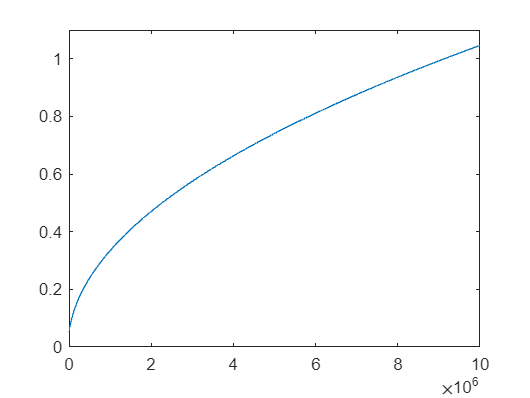

fplot(Ls,[0 1e7]), ylim([0 1.1])